# Sample

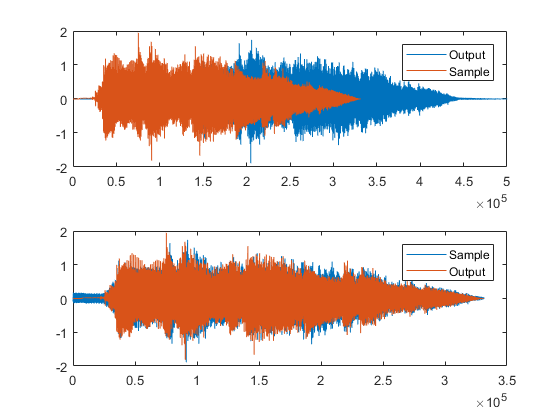

y1 = audioread('Audio/Sample.wav');
y2 = audioread('Audio/output.wav');

End = abs(y2)>0.0245;
End = find(End(:,2),1,'last');

% figure(1)
% subplot(2,1,1)
% plot(y1(:,1)+y1(:,2))
% hold on
% plot(y2(End-length(y1):End,1)+y2(End-length(y1):End,2))
% hold off

figure(2)
clf
subplot(2,1,1)
plot(y2(1:5*10^5,1)+y2(1:5*10^5,2))
hold on
plot(y1(:,1)+y1(:,2))
legend('Output','Sample')

subplot(2,1,2)
plot(y2(End-length(y1):End,1)+y2(End-length(y1):End,2))
hold on
plot(y1(:,1)+y1(:,2))
legend('Sample','Output')
hold off


clear y1 y2

%set(gcf,'position',[0,0,750,400])

# Frequency response

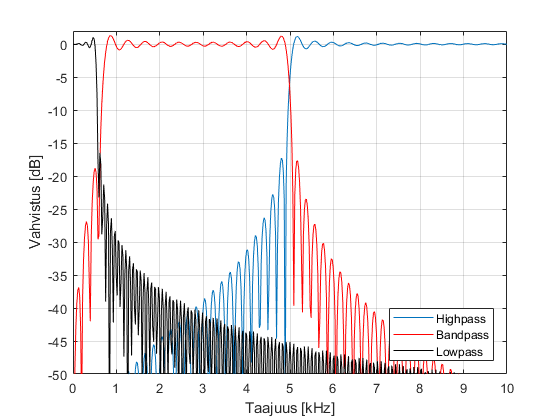

w=linspace(0,22100/1000,1000);
figure(3)
clf
plot(w,20*log10(abs(H_H)))
hold on
plot(w,20*log10(abs(H_B)),'r')
plot(w,20*log10(abs(H_L)),'k')
hold off
axis([0,10,-50, 2])
grid on
xlabel('Taajuus [kHz]')
ylabel('Vahvistus [dB]')
legend('Highpass','Bandpass','Lowpass','location','SE')

# Chirp

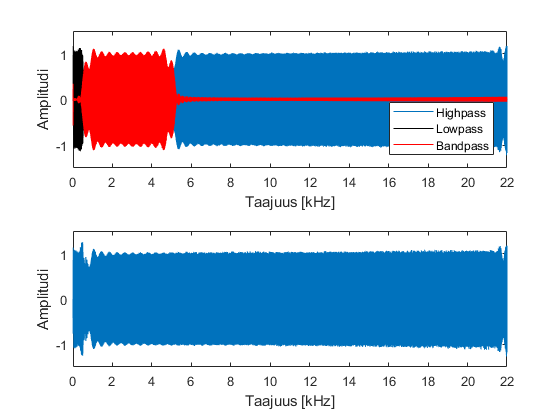

figure(4)
clf
subplot(2,1,1)
w = linspace(0,22100/1000,441001);
wl = linspace(0,22100/1000,110251);
plot(w, Filtered_Highpass.Data)
hold on
plot(wl, Filtered_Lowpass.Data,'k')
plot(w, Filtered_Bandpass.Data,'r')
hold off
axis([0,22,-1.5, 1.5])
ylabel('Amplitudi')
xlabel('Taajuus [kHz]')
legend('Highpass','Lowpass','Bandpass','location','SE')

subplot(2,1,2)
plot(w, Sum.Data)
axis([0,22,-1.5, 1.5])
ylabel('Amplitudi')
xlabel('Taajuus [kHz]')


clear w wl

# PLC

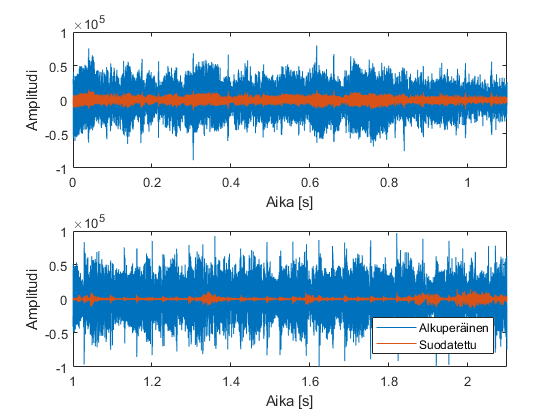

LPcsv = csvread('Mittaukset\Lowpass10.csv',22,0);
BPcsv = csvread('Mittaukset\Bandpass10.csv',22,0);
figure(6);
clf
subplot(2,1,1)
plot(LPcsv(:,1)/10^4,...
    LPcsv(:,2)+LPcsv(:,3)+LPcsv(:,4)+LPcsv(:,5)+LPcsv(:,6))
hold on
plot(LPcsv(:,1)/10^4,LPcsv(:,7))
axis([0,1.1,-1*10^5,1*10^5])
xlabel('Aika [s]')
ylabel('Amplitudi')

subplot(2,1,2)
plot(BPcsv(:,1)/10^4,...
    BPcsv(:,2)+BPcsv(:,3)+BPcsv(:,4)+BPcsv(:,5)+BPcsv(:,6))
hold on
plot(BPcsv(:,1)/10^4,...
    BPcsv(:,7)+BPcsv(:,8)+BPcsv(:,9)+BPcsv(:,10)+BPcsv(:,11))
axis([1,2.1,-1*10^5,1*10^5])
xlabel('Aika [s]')
ylabel('Amplitudi')
legend('Alkuperäinen','Suodatettu','location','SE')


clear LPcsv BPcsv

# Quantization

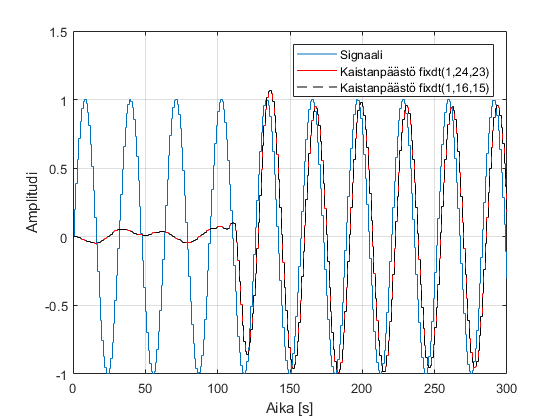

figure(7)
clf
plot(ConvSini)
hold on
plot(ConvBand_23,'r')
plot(ConvBand_15,'k--')
xlabel('Aika [s]')
ylabel('Amplitudi')
legend('Signaali','Kaistanpäästö fixdt(1,24,23)','Kaistanpäästö fixdt(1,16,15)')
axis([0,300,-1,1.5])
grid on